%%%%%%%%%%%%define continue state space%%%%%%%%%%%%%%
syms a b c p q r; 
A=[0 1 0 0;b 0 0 a;0 0 0 1;q 0 0 p];
B=[0;c;0;r];

%%%%%%%%%%%Discretization of a state-space model%%%%%%%%%
%y=theta_1
C=[1 0 0 0];
%a=-0.9421,b=82.7231,c=14.2306,p=-3.7808,q=4.9952,r=57.1120;
A=double(subs(A,{a,b,c,p,q,r},{-0.9421,82.7231,14.2306,-3.7808,4.9952,57.1120}));
B=double(subs(B,{a,b,c,p,q,r},{-0.9421,82.7231,14.2306,-3.7808,4.9952,57.1120}));
D=0;
h=0.1;
%%%%%%continue system%%%%%%%%%%%%%%%%%
sys=ss(A,B,C,D);
%%%%%%discrete system%%%%%%%%%%%%%%%%%
sys_d=c2d(sys,h);
A_d=sys_d.a

A_d =     1.4421    0.1143         0   -0.0045
    9.4370    1.4421         0   -0.0908
    0.0237    0.0008    1.0000    0.0833
    0.4814    0.0237         0    0.6845


B_d=sys_d.b

B_d =     0.0677
    1.3715
    0.2530
    4.7660


C_d=sys_d.c

C_d =      1     0     0     0


%%%%%%delay of the system%%%%%%%%%%%%%
t=0.8*h;
M=expm([A,B;0 0 0 0 0]*t);
At=M(1:4,1:4);
Bt=M(1:4,5);
M2=expm([A,B;0 0 0 0 0]*0.2*h);
A_ht=M2(1:4,1:4);
B_ht=M2(1:4,5);
A11=A_ht*At;
B11=A_ht*Bt;
B22=B_ht;
A_delay=[A11,B11;0 0 0 0 0]

A_delay =     1.4421    0.1143         0   -0.0045    0.0649
    9.4370    1.4421         0   -0.0908    1.0958
    0.0237    0.0008    1.0000    0.0833    0.2419
    0.4814    0.0237         0    0.6845    3.6657
         0         0         0         0         0


B_delay=[B22;1]

B_delay =     0.0028
    0.2757
    0.0111
    1.1002
    1.0000


C_delay=[1 0 0 0 0];
eigvalue_A_d=eig(A_d)

eigvalue_A_d =     1.0000
    2.4781
    0.4008
    0.6899


eigenvalue_A_delay=eig(A_delay)

eigenvalue_A_delay =     1.0000
    2.4781
    0.4008
    0.6899
         0


clc


%%%%%%%characters of LQ problem%%%%%%%%%%%%%%%%%%
A2=[1.0041 0.0100 0 0;0.8281 1.0041 0 -0.0093;0.0002 0.0000 1 0.0098;0.0491 0.0002 0 0.9629];
B2=[0.0007 0.1398 0.0028 0.5605]';
C2=[1 0 0 0;0 0 1 0];
Q=eye(4);
R=1;
Pf=10*eye(4);
N_input=1000;

%%%%%%%calculate with dp%%%%%%%%%%%%%%%%%%%%%%
[K_dp,P0,eigvalue_dp,N] =dp_func(A2,B2,N_input,Q,R,Pf)

This is the result of dp solution
the stable value of dp is 33

K_dp =   -46.1566   -5.2278    0.0155    0.4031


P0 = 	1.0e+04 *

    3.0780    0.3401   -0.0201   -0.0731
    0.3401    0.0382   -0.0023   -0.0082
   -0.0201   -0.0023    0.0042    0.0006
   -0.0731   -0.0082    0.0006    0.0020


eigvalue_dp =     0.5584
    0.9236
    0.9524
    0.9996


N = 33

%%%%%%%%%%solve with idare equation%%%%%%%%%%
fprintf("This is the result of idare solution\n")

This is the result of idare solution


[X,K,L]=idare(A2,B2,Q,R)

X = 	1.0e+04 *

    4.8730    0.5323   -0.1038   -0.1154
    0.5323    0.0587   -0.0114   -0.0127
   -0.1038   -0.0114    0.0125    0.0027
   -0.1154   -0.0127    0.0027    0.0030


K =    67.7456    7.5229   -0.6939   -0.9025


L =    0.9901 + 0.0000i
   0.9156 + 0.0102i
   0.9156 - 0.0102i
   0.5584 + 0.0000i


%%%%%%%%%solve with iteration%%%%%%%%%%%%%%%
aim_error=0.1;
init_error=5;
P_last=Pf;
[i,P_next] = dp_iteration(aim_error,init_error,P_last,A2,B2,Q,R)

This is the result of dp_literation solution
the  value of literation is 426

i = 426

P_next = 	1.0e+04 *

    4.8726    0.5322   -0.1037   -0.1154
    0.5322    0.0587   -0.0114   -0.0127
   -0.1037   -0.0114    0.0125    0.0027
   -0.1154   -0.0127    0.0027    0.0030


%%%%%%%%calculate with new Pf%%%%%%%%
[K_dp,P0,eigvalue_dp,N] =dp_func(A2,B2,N_input,Q,R,P_next)

This is the result of dp solution
the stable value of dp is 1

K_dp =   -67.7421   -7.5226    0.6935    0.9024


P0 = 	1.0e+04 *

    4.8726    0.5322   -0.1037   -0.1154
    0.5322    0.0587   -0.0114   -0.0127
   -0.1037   -0.0114    0.0125    0.0027
   -0.1154   -0.0127    0.0027    0.0030


eigvalue_dp =    0.5584 + 0.0000i
   0.9156 + 0.0102i
   0.9156 - 0.0102i
   0.9901 + 0.0000i


N = 1

%%%%%%%batch solution of the LQ problem%%%%%%%%%%%
[k,eigvalue,N] = batch_func(A2,B2,N_input,Q,R,Pf)

This is the result of batch solution
the stable value of batch is 33

k =   -46.1566   -5.2278    0.0155    0.4031


eigvalue =     0.5584
    0.9236
    0.9524
    0.9996


N = 33

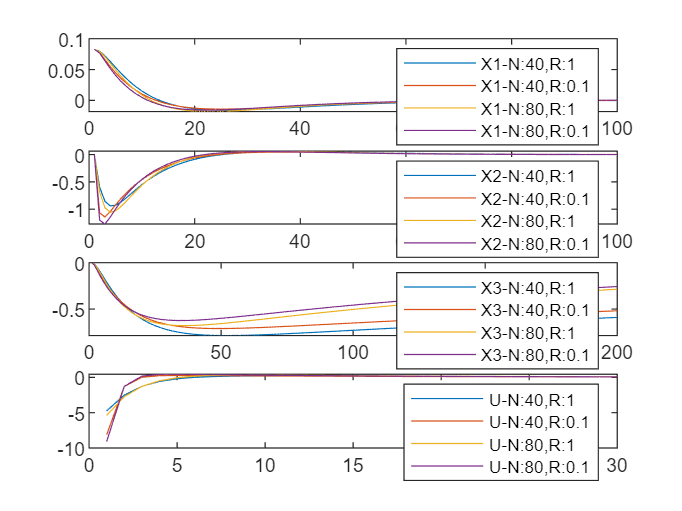

%%%%%%%%%%%%receding horizon control%%%%%%%%%%%%
N_input=40;R=1;X1_steps=100;X2_steps=100;X3_steps=200;U_step=30;
X0=[pi/38 0 0 0]';
K_STEPS=100;
% [kb,omega,gama,Q_bar,R_bar] = MPC_batch(A2,B2,N_input,Q,R,Pf);
[X_K1,uk1,X1_k1,X2_k1,X3_k1,UK1] = xu_plot(A2,B2,N_input,Q,R,Pf,X0,X1_steps,X2_steps,X3_steps,U_step);
N_input=40;R=0.1;
[X_K2,uk2,X1_k2,X2_k2,X3_k2,UK2] = xu_plot(A2,B2,N_input,Q,R,Pf,X0,X1_steps,X2_steps,X3_steps,U_step);
N_input=80;R=1;
[X_K3,uk3,X1_k3,X2_k3,X3_k3,UK3] = xu_plot(A2,B2,N_input,Q,R,Pf,X0,X1_steps,X2_steps,X3_steps,U_step);
N_input=80;R=0.1;
[X_K4,uk4,X1_k4,X2_k4,X3_k4,UK4] = xu_plot(A2,B2,N_input,Q,R,Pf,X0,X1_steps,X2_steps,X3_steps,U_step);
subplot(4,1,1)
%%%%%%%%%%%%%%plot%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
plot(X1_k1);hold on;plot(X1_k2);hold on;plot(X1_k3);hold on;plot(X1_k4)
legend("X1-N:40,R:1","X1-N:40,R:0.1","X1-N:80,R:1","X1-N:80,R:0.1")
hold on 
subplot(4,1,2)
plot(X2_k1);hold on;plot(X2_k2);hold on;plot(X2_k3);hold on;plot(X2_k4)
legend("X2-N:40,R:1","X2-N:40,R:0.1","X2-N:80,R:1","X2-N:80,R:0.1")
hold on 
subplot(4,1,3)
plot(X3_k1);hold on;plot(X3_k2);hold on;plot(X3_k3);hold on;plot(X3_k4)
legend("X3-N:40,R:1","X3-N:40,R:0.1","X3-N:80,R:1","X3-N:80,R:0.1")
hold on 
subplot(4,1,4)
plot(UK1);hold on;plot(UK2);hold on;plot(UK3);hold on;plot(UK4)
legend("U-N:40,R:1","U-N:40,R:0.1","U-N:80,R:1","U-N:80,R:0.1")
hold off

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%%%%%%%%%%%Constrained RHC%%%%%%%%%%%%%%%%%%%%%


